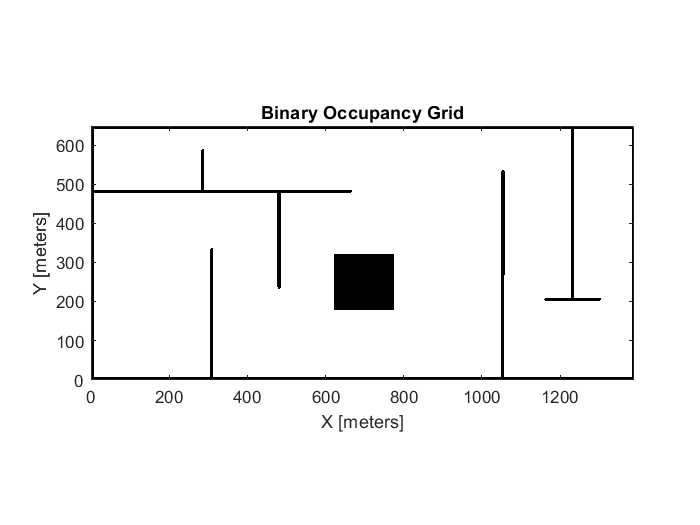

clear
clc

%%Load the map(obstacles).
img = imread('mat1.png');
figure
th = 0.6;
bw = im2bw(img,th);
figure,
%imshow(bw);
map = binaryOccupancyMap(bw,1);
show(map)

%%
prm = mobileRobotPRM;
prm.NumNodes = 1000;
prm.ConnectionDistance = 80;
prm.Map= map;
show(prm)
%%
disp('Click for the start Location');

Click for the start Location


startLocation = ginput(1);
disp('Click for the end Location');

Click for the end Location


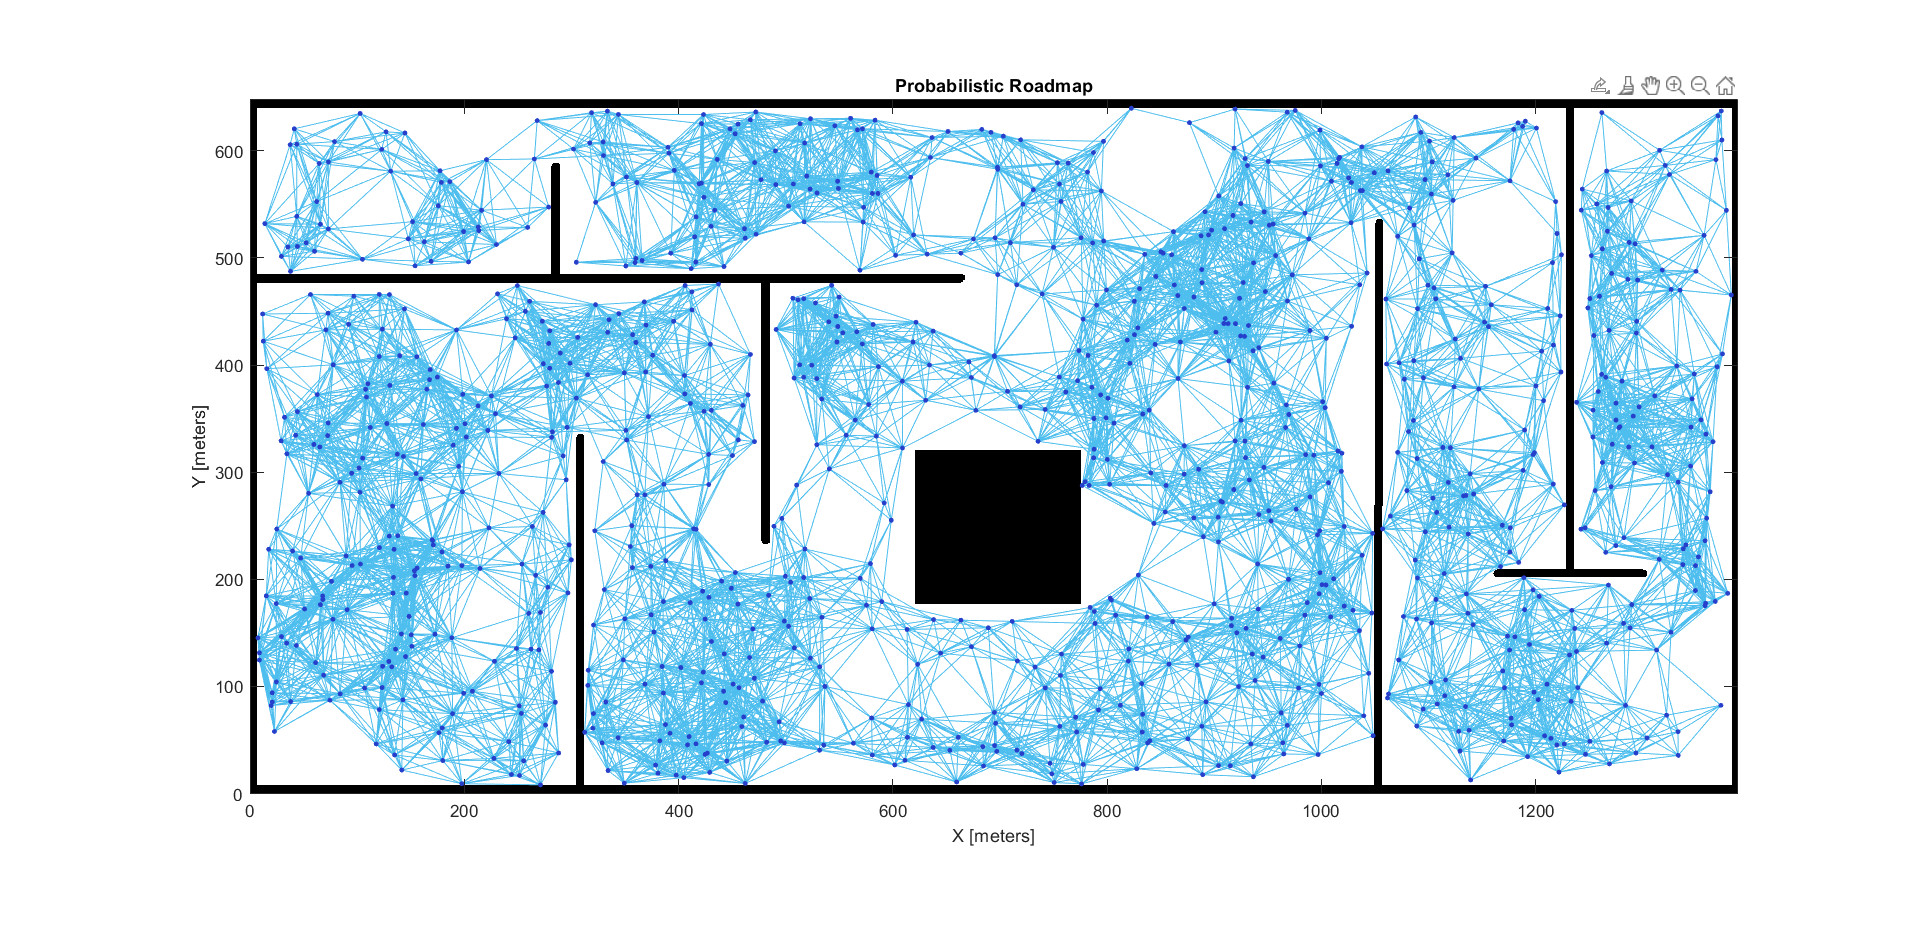

endLocation = ginput(1);

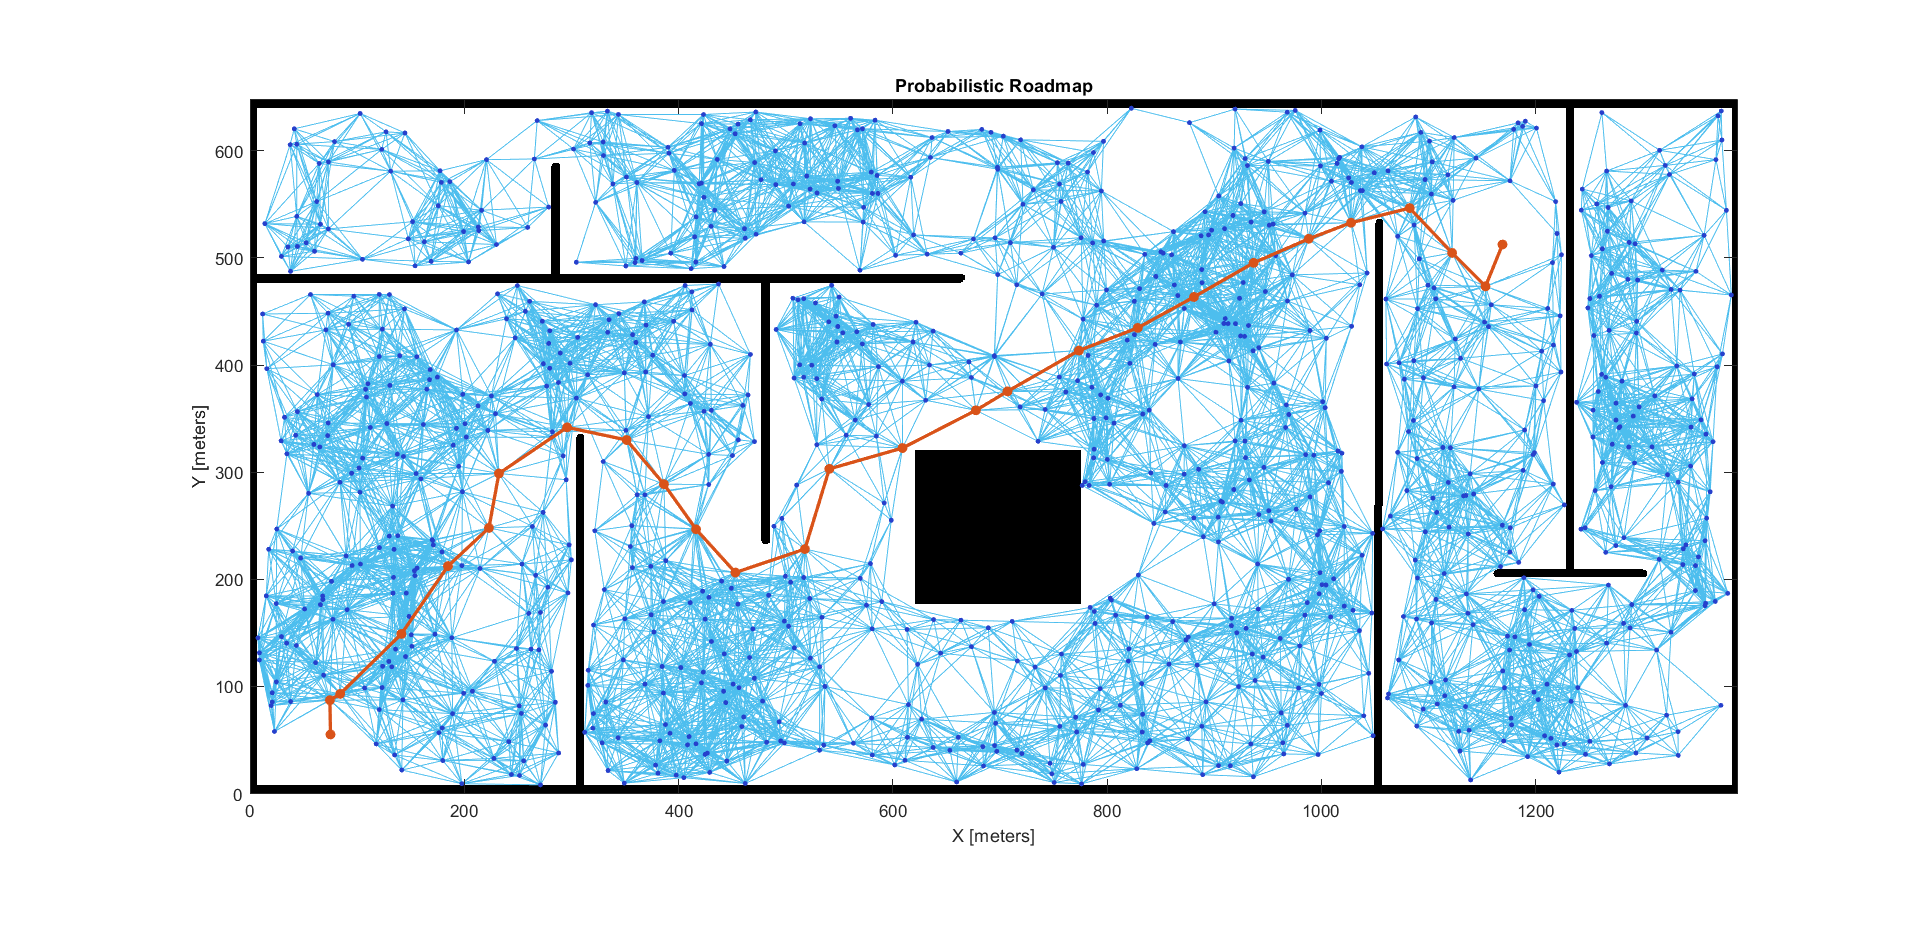

% while isempty(path)
%     prm.NumNodes = prm.NumNodes + 30
%     update(prm)
%     path = findpath(prm,startLocation,endLocation)
%     show(prm)
%     pause(1)
% end
path = findpath(prm,startLocation,endLocation);
show(prm);